clear

## Select data

% Twelve Participants 
participants = {
    "HOBI6W"
    "QH0J5Y"
    "I1PHGZ"
    "E8N9LB"
    "SZFD9P"
    "KEJXS2"
    "UFBOW2"
    "DLB8C7"
    'MQKC6D'
    'JN3R72'
    '2QAC38'
    'U859EF'};

% Three Sessions
sessions = {'S001'
    'S002'
    'S003'};

[participant, ~] = listdlg("ListString", participants);
%[session, ~] = listdlg("ListString", sessions);
session = 3

session = 3

## Data gathering

% Collecting movement data for the left and right foot
leftfootmovementT001 = readmatrix('.\data\' + string(participants(participant)) + '\' + string(sessions(session)) + '\trackers\left_foot_movement_T001.csv');
rightfootmovementT001 = readmatrix('.\data\' + string(participants(participant)) + '\' + string(sessions(session)) + '\trackers\right_foot_movement_T001.csv');

% Collecting the target locations in the environment
targetlocations = readmatrix('.\data\targetlocations.csv');

% ?
log = readmatrix('.\data\' + string(participants(participant)) + '\' + string(sessions(session)) + '\trial_results.csv'); %'\session_info\log.csv'


time = leftfootmovementT001(:,1);
indices = [1:height(time)];
x = leftfootmovementT001(:,2);
y = leftfootmovementT001(:,3);
z = leftfootmovementT001(:,4);

xr = rightfootmovementT001(:,2);
yr = rightfootmovementT001(:,3);
zr = rightfootmovementT001(:,4);

tar_x = targetlocations(:,1);
tar_y = targetlocations(:,2);
tar_z = targetlocations(:,3);

## Find timestamp of measured distances

% Finding the timestamps where a distance-related even occurs 
timestamp = [];
for i = 1:height(log)
    if contains(string(log(i,3)), "distance")
        timestamp = [timestamp; table2array(log(i,1))];
    end
end

## Find timestap locations

% Determining the index in the time array corresponding to each timestamp
triggerindex = [];
for k = 1:height(timestamp)
    for i = 1:height(time)
        if time(i,1) > (timestamp(k,1))
            triggerindex = [triggerindex; i];
            break
        end
    end
end

## Find corresponding position

% Initializing the collision data as empty arrays
collisionr = [];
collisionl = [];

% Extracting collision data for the left and right foot based on the
% trigger indices
for i = 1:height(timestamp)
    if mod(i,2) == 1
        collisionr = [collisionr; xr((triggerindex(i))) yr((triggerindex(i))) zr((triggerindex(i)))];
    end
    if mod(i,2) == 0
        collisionl = [collisionl; x((triggerindex(i))) y((triggerindex(i))) z((triggerindex(i)))];
    end
end

## Find point closest to target

% Initializing the indices of closest points to the target for the right
% and left foot as empty arrays
indicesr = [];
indicesl = [];

for i = 1:16 % This finds the indices of those points
    if mod(i,2) == 1
        [c, index] = min(vecnorm((rightfootmovementT001(:,2:4)-targetlocations(i,1:3))'));
        indicesr = [indicesr; index];
    end
    if mod(i,2) == 0
        [c, index] = min(vecnorm((leftfootmovementT001(:,2:4)-targetlocations(i,1:3))'));
        indicesl = [indicesl; index];
    end
end

% Find coordinates of those values
x_closest = x(indicesl);
y_closest = y(indicesl);
z_closest = z(indicesl);

xr_closest = xr(indicesr);
yr_closest = yr(indicesr);
zr_closest = zr(indicesr);

## Look for minimum value close to previously determined points

mindicesr = [];
mindicesl = [];
searchrange = 30;

for i = 1:8
    if indicesr(i)+searchrange > indices(end)
        [minr, mindexr] = min(yr(indicesr(i)-20:indices(end)));
    else
        [minr, mindexr] = min(yr(indicesr(i)-20:indicesr(i)+searchrange));
    end
    mindexr = mindexr + indicesr(i) - 21;
    mindicesr = [mindicesr; mindexr];
    
    if indicesl(i)+searchrange > indices(end)
        [minl, mindexl] = min(y(indicesl(i)-20:indices(end)));
    else
        [minl, mindexl] = min(y(indicesl(i)-20:indicesl(i)+searchrange));
    end
    mindexl = mindexl + indicesl(i) - 21;
    mindicesl = [mindicesl; mindexl];
end

## Compute new distance from foot to target

distances = [];
for i = 1:8
    coordsr = rightfootmovementT001(mindicesr(i),[2 4]);
    tardist = norm(coordsr - targetlocations(2*i-1,[1 3]));
    distances = [distances; tardist];
    coordsl = leftfootmovementT001(mindicesl(i),[2 4]);
    tardist = norm(coordsl - targetlocations(2*i,[1 3]));
    distances = [distances; tardist];
end

## Find time between steps

timeindex = zeros(16,1)

timeindex =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


for i = 1:8
    timeindex(2*i-1) = mindicesr(i)
    timeindex(2*i) = mindicesl(i)
end

timeindex =    251
     0
     0
     0
     0
     0
     0
     0
     0
     0


timeindex =    251
   369
     0
     0
     0
     0
     0
     0
     0
     0


timeindex =    251
   369
   482
     0
     0
     0
     0
     0
     0
     0


timeindex =    251
   369
   482
   602
     0
     0
     0
     0
     0
     0


timeindex =    251
   369
   482
   602
   720
     0
     0
     0
     0
     0


timeindex =    251
   369
   482
   602
   720
   838
     0
     0
     0
     0


timeindex =    251
   369
   482
   602
   720
   838
   976
     0
     0
     0


timeindex =          251
         369
         482
         602
         720
         838
         976
        1242
           0
           0


timeindex =          251
         369
         482
         602
         720
         838
         976
        1242
        1256
           0


timeindex =          251
         369
         482
         602
         720
         838
         976
        1242
        1256
        1389


timeindex =          251
         369
         482
         602
         720
         838
         976
        1242
        1256
        1389


timeindex =          251
         369
         482
         602
         720
         838
         976
        1242
        1256
        1389


timeindex =          251
         369
         482
         602
         720
         838
         976
        1242
        1256
        1389


timeindex =          251
         369
         482
         602
         720
         838
         976
        1242
        1256
        1389


timeindex =          251
         369
         482
         602
         720
         838
         976
        1242
        1256
        1389


timeindex =          251
         369
         482
         602
         720
         838
         976
        1242
        1256
        1389



times = time(timeindex);
tibs = zeros(height(times),1);
for i = 1:height(times)
    if i == 1
        tibs(i) = times(i)-times(1);
    end
    if i > 1
        tibs(i) = times(i)-times(i-1);
    end
end

## Height of step

%

## Plot 3D

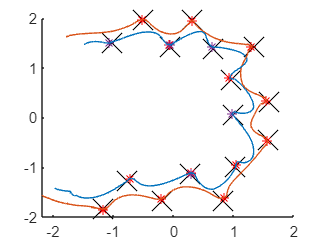

clf;
figure(1)
hold on
% Plot movement of trackers
plot3(x, z, y);
plot3(xr, zr, yr);
s = 300;

% Plot target locations (y is not correct)
scatter3(tar_x, tar_z, tar_y, s, 'x', 'black');

% Plot detected collisions (these are not correct)
%scatter3(collisionr(:,1), collisionr(:,3), collisionr(:,2), s/2, 'cyan');
%scatter3(collisionl(:,1), collisionl(:,3), collisionl(:,2), s/2, 'cyan');

% Plot closest point on path to target
scatter3(x_closest, z_closest, y_closest, '*');
scatter3(xr_closest, zr_closest, yr_closest, '*');

% Plot new detection point
scatter3(x(mindicesl), z(mindicesl), y(mindicesl), '*', 'red');
scatter3(xr(mindicesr), zr(mindicesr), yr(mindicesr), '*', 'red');
hold off

## Plot 2D

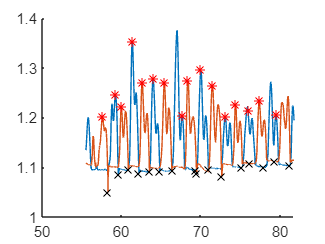

clf;
figure(2)
hold on
% Plot y position over time
plot(time, y);
plot(time, yr);

% Plot timestamp where collision is detected
scatter(timestamp(2:2:end), y(triggerindex(2:2:end)), 'cyan');
scatter(timestamp(1:2:end), yr(triggerindex(1:2:end)), 'cyan');
 
% Plot timestamp where new detection point is
scatter(time(mindicesl), y(mindicesl), 'x', 'black');
scatter(time(mindicesr), yr(mindicesr), 'x', 'black');
 
% Plot timestamp where max is
scatter(time(maxdicesr), yr(maxdicesr), '*', 'red');
scatter(time(maxdicesl), y(maxdicesl), '*', 'red');
hold off

## Step Height Plot

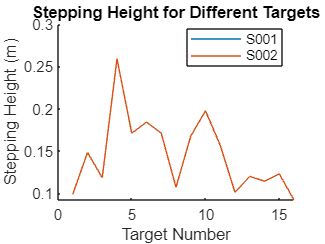

%clf;
%figure(3)
%plot(stepheight)
%xlabel('Target Number');
%ylabel('Stepping Height (m)');
%title('Stepping Height for Different Targets (no-body representation)');
%hold on;

clf;
figure(3);
hold on;

% Initialize cell array to store step height data for each session
stepheight_data = cell(1, 3);

% Initialize legend entries
legend_entries = cell(1, 3);

for session = 1:3
    leftfootmovementT001 = readmatrix('.\data\' + string(participants(participant)) + '\' + string(sessions(session)) + '\trackers\left_foot_movement_T001.csv');
    rightfootmovementT001 = readmatrix('.\data\' + string(participants(participant)) + '\' + string(sessions(session)) + '\trackers\right_foot_movement_T001.csv');
    
    stepheight = calculateStepHeight(leftfootmovementT001, rightfootmovementT001, mindicesr, mindicesl, yr, y);

    % Store step height data for the current session
    stepheight_data{session} = stepheight;
    
    % Store legend entry for the current session
    legend_entries{session} = sessions{session};
end

% Plot all step height data
for session = 1:3
    plot(stepheight_data{session}, 'DisplayName', legend_entries{session});
end

xlabel('Target Number');
ylabel('Stepping Height (m)');
title('Stepping Height for Different Targets');
legend('Location', 'best'); % Display legend entries together

function stepheight = calculateStepHeight(leftfootmovementT001, rightfootmovementT001, mindicesr, mindicesl, yr, y)
    
    maxdicesr = zeros(8,1);
    maxdicesl = zeros(8,1);
    stepheight = zeros(16,1);
    for i = 1:8
        if mindicesr(i)-180 < 1
            [maxr, maxdexr] = max(yr(1:mindicesr(i)));
        else
            [maxr, maxdexr] = max(yr(mindicesr(i)-180:mindicesr(i)));
            maxdexr = maxdexr + mindicesr(i) - 181;
        end
        maxdicesr(i) = maxdexr;
        stepheight(2*i-1) = yr(maxdexr) - yr(mindicesr(i)+15);
        
        if mindicesl(i)-180 < 1
            [maxl, maxdexl] = max(y(1:mindicesl(i)));
        else
            [maxl, maxdexl] = max(y(mindicesl(i)-180:mindicesl(i)));
            maxdexl = maxdexl + mindicesl(i) - 181;
        end
        maxdicesl(i) = maxdexl;
        stepheight(2*i) = y(maxdexl) - y(mindicesl(i)+15);
    end
end